# discussion of the computation efficiency

# the results are comptued from the SINEX files from the offical open service as well as from the simulation to discuss the computation efficiency of the FALCON algorithm.

% More details about the algorithm refer to   Ampatzidis D, Wang L, Mouratidis A, Balidakis K (2022) Rigorous and fast constraints transformations at the solution level: case studies for regional and global GNSS networks. GPS Solut 26(2):44. [https://doi.org/10.1007/s10291-022-01225-3](https://doi.org/10.1007/s10291-022-01225-3)

% questions regarding on script feel free to submit request via github: github.com/drlwang/falcon or contact us via the github or contact email listed in the paper.

## section I: plot the CPU time from SINEX file



% flg_figsav = false;
% % SIR16887  igs20P21251_all IGS1R03SNX_20170010000_07D_07D_SOL
% statnum = [203 636 1054];
% % alternative computation time for each IC2OC computation in milisecond
% time_alt = [10 55 160]./1000;
% time_cls = [70 1650 7580]./1000;
% 
% pltdir = ['./figures/general'];
% 
% fighdl = figure('color','w');
% h1 =plot(statnum,time_alt,'k^','MarkerSize',10);
% hold on
% h2 =plot(statnum,time_cls,'k+','MarkerSize',10);
% xlim([150 1100])
% ylim([-2 15])
% xlabel('number of station')
% ylabel('computation time (s)')
% pbaspect([2 1 1])
% yyaxis right
% 
% h3 =plot(statnum,time_cls./time_alt,'o','MarkerSize',10);
% 
% ylabel('ratio t_c_l_s/t_a_l_t')
% 
% legend([h1 h2 h3],{'t_a_l_t','t_c_l_s','t_c_l_s/t_a_l_t'},'location','NW')
% 
% % export to file
% figname = ['IC2OC_computation_time_3case'];
% set(fighdl,'name',figname,'NumberTitle','Off');
% if flg_figsav
%     savefigures( fighdl,fullfile(pltdir,figname),{'-png','-eps','-fig'},'-openGL',false );
% end


## section II: plot the CPU time from simulation

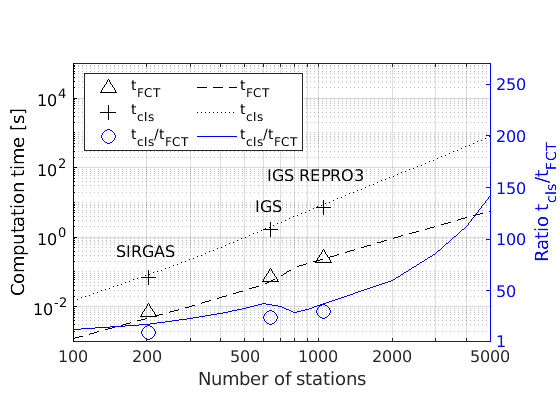



% cls:         0.08614 s alt :         0.00597 s  ratio:    14 statNum:    202 loop:  1   
% cls:         2.07895 s alt :         0.05125 s  ratio:    41 statNum:    636 loop:  1   
% cls:         8.72789 s alt :         0.25004 s  ratio:    35 statNum:   1054 loop:  1 

% LC2OC (NNT+NNR) cls:      1.67217 s alt :      0.06476 s ratio:     26 statNum:  636 

fontSize = 12;
set(0,'defaultAxesFontSize',fontSize) % set the default fontsize-> use 12 for the GPS solution
    
flg_figsav = true;
% SIR16887  igs20P21251_all IGS1R03SNX_20170010000_07D_07D_SOL
statnum = [203 636 1053];
% alternative computation time for each IC2OC computation in milisecond
% time_alt = [10 55 160]./1000;
% time_cls = [70 1650 7580]./1000;
time_cls = [0.067767 1.676961 7.404818];
time_alt = [0.006953 0.067877 0.248425]; % averaged from the ten time computation
strSolLabelCls = '_c_l_s';
strSolLabelAlt = '_F_C_T';
%  readTimeLst =load('time_simulation.csv');
%  allTimeLst = zeros(3,14,10);
%  allTimeLst(1,:,:) = repmat(readTimeLst(1:2:28),1,1,10);
%  
%  for cdx = 1:10     
%      for sdx = 1:14
%          allTimeLst(2,sdx,cdx) = readTimeLst((sdx-1)*2+(cdx-1)*28+1,2);
%          allTimeLst(3,sdx,cdx) = readTimeLst((sdx-1)*2+(cdx-1)*28+2,2);
%      end
%  end
 load('cmp_IC2OC_clsVSalt_v3.mat','cmpTimeList');
 allTimeLst = cmpTimeList(:,:,1:5);
 
 avgTimeLst =mean(allTimeLst,3);
 avgTimeLst(2:3,:)=avgTimeLst(2:3,:);
 
 
pltdir = ['./figures/general'];

fighdl = figure('color','w');
colororder({'k','b'})
yyaxis left

% h1 =plot(statnum,time_alt,'k^','MarkerSize',10);
h1 =loglog(statnum,time_alt,'k^','MarkerSize',10);

hold on
h2 =plot(statnum,time_cls,'k+','MarkerSize',10);
h4 = plot(avgTimeLst(1,:),avgTimeLst(3,:),'LineStyle',"--"); % alternative
h5 = plot(avgTimeLst(1,:),avgTimeLst(2,:),'LineStyle',":"); % classic
ylim([10e-4 10e4])

fntsz = fontSize;
text(150,0.4,'SIRGAS','FontSize',fntsz)
text(550,8,'IGS','FontSize',fntsz)
text(620,60,'IGS REPRO3','FontSize',fntsz)

xlim([100 5000])
% ylim([0 270])
xlabel('Number of stations')
ylabel('Computation time [s]')
pbaspect([1.5 1 1])

grid on

yyaxis right

h3 =plot(statnum,time_cls./time_alt,'o','MarkerSize',10);
hold on

h6 = plot(avgTimeLst(1,:), avgTimeLst(2,:)./avgTimeLst(3,:),'LineStyle',"-");
xlim([0 5000])
ylim([1 270])
yticks([1 50 100 150 200 250])
ylabel(['Ratio t',strSolLabelCls,'/','t',strSolLabelAlt])
legend([h1 h2 h3 h4 h5 h6],{['t',strSolLabelAlt],['t',strSolLabelCls], ...
    ['t',strSolLabelCls,'/','t',strSolLabelAlt],['t',strSolLabelAlt], ...
    ['t',strSolLabelCls],['t',strSolLabelCls,'/t',strSolLabelAlt]},'location','NW','NumColumns',2)
xticks([100:100:1000 2000:1000:5000])
xticklabels({'100','200','','','500','','','','','1000','2000','','','5000'})
% export to file
figname = ['IC2OC_computation_time_3case_simulation'];
set(fighdl,'name',figname,'NumberTitle','Off');
if flg_figsav
    savefigures( fighdl,fullfile(pltdir,figname),{'-png','-eps','-fig'},'-openGL',false );
end

## section: III overlap the residual plot

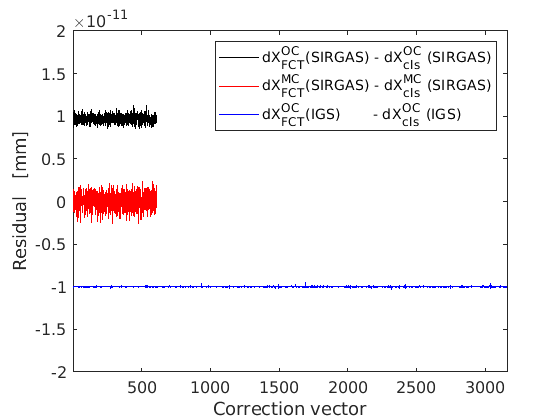

load(fullfile('/g1/lwang/develop/DFG/snxtool/DA_constrain/figures','Constrain_paper_residuals.mat'),'dx_diff_OC2MC','dx_diff_MC2OC')

flg_figsav = true;
fontSize = 12;
set(0,'defaultAxesFontSize',fontSize)


plt_scale= 1000; % change meter to mm
fighdl = figure('color','w');

plotMax = 1e-11;

strSolLabelCls = '_c_l_s';
strSolLabelAlt = '_F_C_T';

% dx_diff_OC2MC

h1 = plot(1:length(dx_diff_MC2OC{1,1}),(dx_diff_MC2OC{1,1})*plt_scale +plotMax,'color','k');
hold on;
h2 = plot(1:length(dx_diff_MC2OC{3,1}),(dx_diff_MC2OC{3,1})*plt_scale -plotMax,'color','b');
h3 = plot(1:length(dx_diff_OC2MC{1,1}),(dx_diff_OC2MC{1,1})*plt_scale,'color','r');


ldgstr = { ['dX^O^C', strSolLabelAlt,'(SIRGAS) - dX^O^C', strSolLabelCls,' (SIRGAS)'],  ...
    ['dX^M^C', strSolLabelAlt,'(SIRGAS) - dX^M^C', strSolLabelCls,' (SIRGAS)'],         ...
    ['dX^O^C', strSolLabelAlt,'(IGS)       - dX^O^C', strSolLabelCls,' (IGS)   ']};

ylabel('Residual   [mm]','FontSize',fontSize)
%         ylabel('Residual   $dX^{OC}_{alt}-dX^{OC}_{cls}$  [mm]','interpreter','Latex','FontSize',fontSize)

xlabel('Correction vector','FontSize',fontSize)
xlim([1,3*max(statnum)])
ylim([-2*plotMax 2*plotMax])
figname = ['IC2OC_altVsCls_all_OC2MC'];
set(fighdl,'name',figname,'NumberTitle','Off');

legend([h1,h3,h2],ldgstr);
if flg_figsav
    savefigures( fighdl,fullfile('/g1/lwang/develop/DFG/snxtool','DA_constrain',['figures'],'general',figname),{'-png','-eps','-fig'},'-openGL',false );
end